# Generate a Control Loookup Table for Controlling the Walker

clear;clc;

pdw.l1 = 2; pdw.l2 = 2;
pdw.m1 = 0.5; pdw.m2 = 0.5; pdw.mh = 0.5;

pdw.gamma = 0; % Fixed for this Experiment
pdw.fps = 10;
deltat = 2;
L = 10;
x = 1.5; 
y = (L-x)*tan(pdw.gamma);

## Generate Input Set

n = 25;
th1d_a = linspace(-5,0,n);
th2_a = linspace(0,pi/4,n);
lookup_table = [];
foot_anchor_fixed = [x;y;1];
tsim = [];
qsim = [];
foot_anchor = [];

for i=1:length(th1d_a)
    for j=1:length(th2_a)
        q0 = [0;th2_a(j);th1d_a(i);0];
        [t,q,q0next,foot_anchor_temp] = one_step(0,deltat,q0,pdw,foot_anchor_fixed);
        flag = true;
        val = 0;
        for k=1:size(q,1)
            th1 = q(k,1); th2 = q(k,2);
            Ggh = [foot_anchor_temp(1,end) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)); ...
            foot_anchor_temp(2,end) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))];
            GgC2 = [foot_anchor_temp(1,end) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + pdw.l2*(cos(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + sin(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))); ... 
            foot_anchor_temp(2,end) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - pdw.l2*(cos(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - sin(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)))];
    
            val1 = Ggh(2) - (L-Ggh(1))*tan(pdw.gamma);
            val2 = GgC2(2) - (L-GgC2(1))*tan(pdw.gamma);
            if val1 < 0 || val2 < 0
                flag = false;
                break
            end
        end
        
        if flag
            tsim = [tsim; t(1:end,:)];
            qsim = [qsim; q(1:end,:)]; 
            foot_anchor = [foot_anchor foot_anchor_temp(:,1:end)];  
            lookup_table = [lookup_table; th1d_a(i) q0next(3) th2_a(j)];
        end
    end
end

## Animate and Check

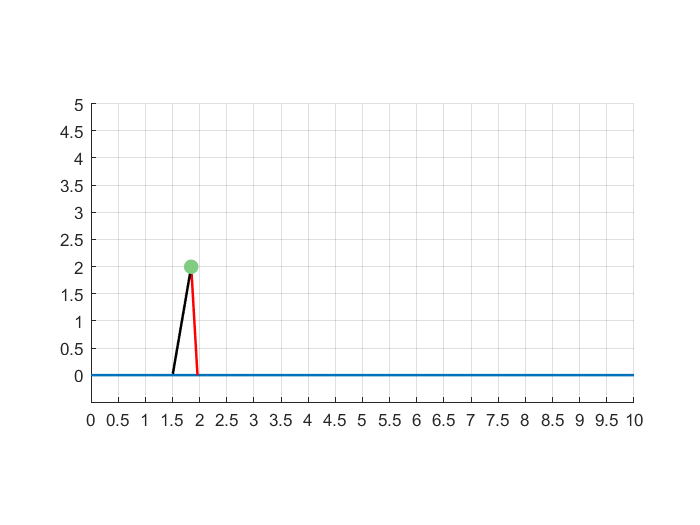

figure(1);
for k=1:length(tsim)
    th1 = qsim(k,1); th2 = qsim(k,2);
    Ggh = [foot_anchor(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)); ...
        foot_anchor(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))];
    GgC2 = [foot_anchor(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + pdw.l2*(cos(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + sin(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))); ... 
        foot_anchor(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - pdw.l2*(cos(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - sin(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)))];
    
    if foot_anchor(3,k) > 0
        leg1_color = 'black';
        leg2_color = 'red';
    else
        leg1_color = 'red';
        leg2_color = 'black';
    end
    
    grid on;
    hold on;
    line([0 L],[L*tan(pdw.gamma) 0],'LineWidth',1.5); % Ramp
    h1 = line([foot_anchor(1,k) Ggh(1)],[foot_anchor(2,k) Ggh(2)],'LineWidth',1.5,'Color',leg1_color); % Stance Leg
    h2 = line([Ggh(1) GgC2(1)],[Ggh(2) GgC2(2)],'LineWidth',1.5,'Color',leg2_color); % Swing Leg
    h3 = plot(Ggh(1),Ggh(2),'.','MarkerSize',30,'Color',[0.5 0.8 0.5]); % Hip

    axis([0 L -0.5 L/2]);
    xticks(0:0.5:L);
    yticks(0:0.5:L);
    daspect([1 1 1]);
    drawnow;
    
    % pause(0.5);
    if k ~= length(tsim)
        delete(h1);
        delete(h2);
        delete(h3);
        % delete(h4);
    end    
end

## Fit a Regression Model

X = [ones(size(lookup_table,1),1) lookup_table(:,1) lookup_table(:,2)];
b = regress(lookup_table(:,3),X)'

b =     0.3471   -0.2985    0.3479
